# 1

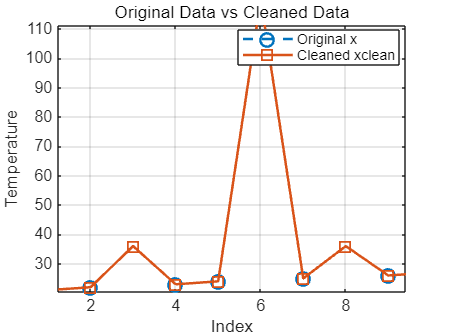

clear; clc 

%% (a) 원본 벡터 생성
x = [21, 22, NaN, 23, 24, 120, 25, NaN, 26, 27];

%% (b) 결측치 위치 저장
idxmissing = isnan(x);

%% (c) 결측치를 제외한 평균과 표준편차 계산
mu0 = mean(x, 'omitnan');
sig0 = std(x, 'omitnan');

%% (d) 평균에서 3sigma 초과하여 벗어난 값을 이상치로 정의
idxoutlier = abs(x - mu0) > 3 * sig0;

%% (e) 원본 벡터 복사 후 결측치와 이상치를 NaN으로 변경
xtemp = x;
xtemp(idxmissing | idxoutlier) = NaN;

%% (f) xtemp의 NaN 값을 xtemp의 평균값으로 대체
mu_temp = mean(xtemp, 'omitnan');

xclean = xtemp;
xclean(isnan(xclean)) = mu_temp;

%% (g) 최종 정제 벡터의 평균과 표준편차 계산
muclean = mean(xclean);
sigclean = std(xclean);

%% (h) 원본 데이터와 정제 데이터 그래프
figure
idx = 1:length(x);

plot(idx, x, 'o--', 'LineWidth', 1.5, 'MarkerSize', 8)
hold on
plot(idx, xclean, 's-', 'LineWidth', 1.5, 'MarkerSize', 8)

grid on
xlabel('Index')
ylabel('Temperature')
title('Original Data vs Cleaned Data')
legend('Original x', 'Cleaned xclean', 'Location', 'best')

xlim([1 length(x)])

hold off

# 2

clear; clc 
%% (a) 숫자 행렬 A 생성
A = [10 200 0.5;
     12 180 0.7;
     15 220 0.6;
     20 250 0.9;
     25 300 1.1];

%% (b) 각 열의 최솟값, 최댓값 저장
colMin = min(A);
colMax = max(A);

%% (c) 각 열을 독립적으로 Min-Max 정규화
A_norm = (A - colMin) ./ (colMax - colMin);

%% (d) 정규화된 행렬 A_norm에서 각 행의 평균 계산
rowMean = mean(A_norm, 2);

%% (e) rowMean이 가장 큰 행 번호 저장
[~, idx] = max(rowMean);

%% (f) idx에 해당하는 원본 행과 정규화된 행 저장
bestOriginal = A(idx, :);
bestNormalized = A_norm(idx, :);


# 3

clear; clc 

%% (a) Channel, Signal, Noise 변수 생성 후 table T 생성
Channel = ["CH1"; "CH2"; "CH3"; "CH4"; "CH5"; "CH6"; "CH7"; "CH8"];

Signal = [18.2; 
          15.5; 
          21.0; 
          11.7; 
          25.3; 
          19.4; 
          28.6; 
          16.8];

Noise = [2.1; 
         3.4; 
         2.8; 
         4.2; 
         3.0; 
         5.1; 
         2.9; 
         3.7];

T = table(Channel, Signal, Noise);

%% (b) SignalToNoise 새 변수 추가
T.SignalToNoise = T.Signal ./ T.Noise;

%% (c) SignalToNoise의 평균값 저장
meanSNR = mean(T.SignalToNoise);

%% (d) SignalToNoise가 meanSNR보다 큰 행만 추출
T_high = T(T.SignalToNoise > meanSNR, :);

%% (e) T_high에서 SignalToNoise 값만 중괄호 {}로 숫자 벡터 추출
snrVec = T_high{:, 'SignalToNoise'};

%% (f) snrVec의 분산 저장
varSNR = var(snrVec);


# 4

clear; clc 

%% (a), (b) wine.data를 table Wine으로 불러오기

varNames = {'Class', ...
            'Alcohol', ...
            'MalicAcid', ...
            'Ash', ...
            'Alcalinity', ...
            'Magnesium', ...
            'Phenols', ...
            'Flavanoids', ...
            'Nonflavanoid', ...
            'Proanthocyanins', ...
            'ColorIntensity', ...
            'Hue', ...
            'OD280', ...
            'Proline'};

Wine = readtable('wine.data', ...
                 'FileType', 'text', ...
                 'Delimiter', ',', ...
                 'ReadVariableNames', false);

Wine.Properties.VariableNames = varNames;

%% (c) Alcohol, MalicAcid, ColorIntensity 세 변수만 선택하여 숫자 행렬 X 생성

X = Wine{:, {'Alcohol', 'MalicAcid', 'ColorIntensity'}};

%% (d) X의 각 열을 Z-score 방식으로 표준화

X_std = zscore(X);

%% (e) X_std에서 각 행의 Euclidean norm 계산

normVec = sqrt(sum(X_std.^2, 2));

% 또는 다음처럼 써도 됨
% normVec = vecnorm(X_std, 2, 2);

%% (f) normVec의 90번째 백분위수 값을 cutoff에 저장

cutoff = prctile(normVec, 90);

%% (g) normVec >= cutoff인 행만 Wine에서 추출

Ttop = Wine(normVec >= cutoff, :);

%% (h) Ttop에서 지정한 변수만 table 형태로 출력

Ttop(:, {'Class', 'Alcohol', 'MalicAcid', 'ColorIntensity'})

ans = 18×4 table
    Class    Alcohol    MalicAcid    ColorIntensity
    _____    _______    _________    ______________

      2       11.41       0.74            3.08     
      2       11.03       1.51             1.9     
      2       13.05        5.8             2.6     
      3       12.53       5.51               5     
      3       13.62       4.95             4.4     
      3       13.88       5.04             4.9     
      3       12.79       2.67            10.8     
      3       13.23        3.3           10.52     
      3       13.17       5.19             7.9     
      3       13.84       4.12            9.01     
      3       14.34       1.68              13     
      3       13.48       1.67           11.75     
      3       13.45        3.7           10.68     
      3        13.4        4.6             8.5     
      3       14.16       2.51             9.7     
      3       13.71       5.65             7.7     


# 5

clear; clc 

%% (a) 평균 50, 표준편차 5를 갖는 길이 100의 열벡터 y 생성
rng(0)   % 난수 seed 고정

y = 50 + 5 * randn(100, 1);

%% (b) 지정된 위치에 이상치 삽입
y([10, 25, 40, 70, 90]) = [90, 95, 5, 100, 0];

%% (c) quantile을 사용하여 Q1, Q3 계산
Q1 = quantile(y, 0.25);
Q3 = quantile(y, 0.75);

%% (d) IQR 계산
IQRval = Q3 - Q1;

%% (e) IQR 기준 하한값 lower, 상한값 upper 계산
lower = Q1 - 1.5 * IQRval;
upper = Q3 + 1.5 * IQRval;

%% (f) IQR 기준 이상치 위치를 논리벡터로 저장
idxoutlier = (y < lower) | (y > upper);

%% (g) 이상치를 제외한 데이터 저장 및 중앙값 계산
yclean = y(~idxoutlier);

medclean = median(yclean);

# 6

clear; clc 

%% (a) 데이터를 table DeviceData로 생성
Device = ["D1"; "D2"; "D3"; "D4"; "D5"; "D6"; ...
          "D7"; "D8"; "D9"; "D10"; "D11"; "D12"];

Power = [110; 130; 125; 160; 170; 150; ...
         190; 200; 210; 180; 220; 240];

Throughput = [42; 50; 48; 61; 65; 57; ...
              72; 75; 79; 69; 83; 91];

DeviceData = table(Device, Power, Throughput);

%% (b) Power와 Throughput을 점 표기법으로 추출
power = DeviceData.Power;
throughput = DeviceData.Throughput;

%% (c) 상관계수 행렬 R과 상관계수 rValue 저장
R = corrcoef(power, throughput);

rValue = R(1, 2);

%% (d) 상관계수 기준에 따라 문장 출력
if rValue >= 0.7
    disp('Strong correlation')
else
    disp('Weak correlation')
end

Strong correlation


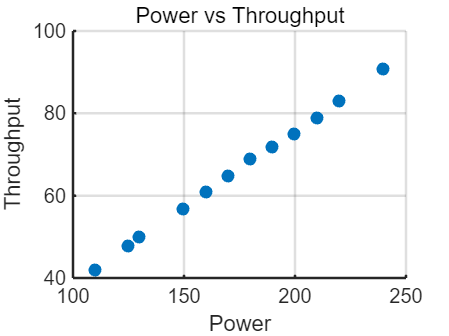


%% (e), (f) scatter plot 작성 및 그래프 꾸미기
figure
scatter(power, throughput, 60, 'filled')

grid on
xlabel('Power')
ylabel('Throughput')
title('Power vs Throughput')

ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1.5;

# 7

clear; clc 

%% (a) 데이터 table Battery 생성
Material = ["A"; "A"; "A"; "A"; ...
            "B"; "B"; "B"; "B"; ...
            "C"; "C"; "C"; "C"];

EnergyDensity = [245; 252; 238; 260; ...
                 310; 295; 305; 318; ...
                 180; 190; 176; 185];

Battery = table(Material, EnergyDensity);

%% (b) 소재 A, B, C에 해당하는 논리 인덱스 생성
idxA = strcmp(Battery.Material, "A");
idxB = strcmp(Battery.Material, "B");
idxC = strcmp(Battery.Material, "C");

% 문자열 비교로 해도 됨
% idxA = Battery.Material == "A";
% idxB = Battery.Material == "B";
% idxC = Battery.Material == "C";

%% (c) logical indexing으로 평균 에너지 밀도 계산
meanA = mean(Battery.EnergyDensity(idxA));
meanB = mean(Battery.EnergyDensity(idxB));
meanC = mean(Battery.EnergyDensity(idxC));

%% (d) 소재별 표준편차 계산
stdA = std(Battery.EnergyDensity(idxA));
stdB = std(Battery.EnergyDensity(idxB));
stdC = std(Battery.EnergyDensity(idxC));

%% (e) 소재명, 평균, 표준편차를 포함하는 요약 table Summary 생성
MaterialName = ["A"; "B"; "C"];
MeanEnergyDensity = [meanA; meanB; meanC];
StdEnergyDensity = [stdA; stdB; stdC];

Summary = table(MaterialName, MeanEnergyDensity, StdEnergyDensity);
Summary

Summary = 3×3 table
    MaterialName    MeanEnergyDensity    StdEnergyDensity
    ____________    _________________    ________________

        "A"              248.75               9.4296     
        "B"                 307               9.6264     
        "C"              182.75               6.0759     



%% (f) groupsummary로 평균과 표준편차 계산한 table G 생성
G = groupsummary(Battery, "Material", {"mean", "std"}, "EnergyDensity");
G

G = 3×4 table
    Material    GroupCount    mean_EnergyDensity    std_EnergyDensity
    ________    __________    __________________    _________________

      "A"           4               248.75               9.4296      
      "B"           4                  307               9.6264      
      "C"           4               182.75               6.0759      


# 8

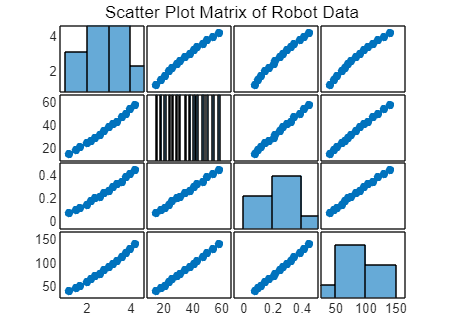

clear; clc 

%% (a) 위 데이터를 table Robot으로 생성
Speed = [1.2; 1.5; 1.7; 2.0; 2.2; ...
         2.4; 2.6; 2.8; 3.0; 3.2; ...
         3.4; 3.6; 3.8; 4.0; 4.2];

Torque = [15; 18; 21; 24; 26; ...
          29; 31; 35; 38; 41; ...
          43; 47; 50; 54; 58];

SlipRate = [0.08; 0.10; 0.12; 0.15; 0.18; ...
            0.21; 0.22; 0.25; 0.27; 0.30; ...
            0.33; 0.35; 0.39; 0.42; 0.45];

EnergyUse = [42; 48; 53; 61; 66; ...
             72; 77; 85; 91; 98; ...
             105; 113; 121; 130; 140];

Robot = table(Speed, Torque, SlipRate, EnergyUse);

%% (b) table2array를 사용하여 숫자 변수들을 행렬 X로 변환
X = table2array(Robot);

%% (c) plotmatrix를 이용하여 변수 간 산점도 행렬 그리기
figure(3)
plotmatrix(X)

title('Scatter Plot Matrix of Robot Data')


%% (d) 각 변수의 분산을 계산하여 행벡터 varVec에 저장
varVec = var(X);

%% (e) varVec에서 가장 큰 값을 갖는 위치 저장
[~, idxMax] = max(varVec);

%% (f) 가장 분산이 큰 변수의 이름 저장
varNames = Robot.Properties.VariableNames;

maxVarName = varNames{idxMax};

# 9

clear; clc
%% (a) train.csv를 table T로 불러오기
T = readtable('train.csv');

%% (b) Age의 결측치 개수 저장
numMissingAge = sum(isnan(T.Age));

%% (c) Age의 결측치를 Age 평균값으로 대체
muAge = mean(T.Age, 'omitnan');

T.Age(isnan(T.Age)) = muAge;

%% (d) Fare의 평균과 표준편차 계산
muFare = mean(T.Fare, 'omitnan');
sigFare = std(T.Fare, 'omitnan');

%% (e) 3sigma 기준으로 Fare 이상치가 아닌 행만 추출
idxFareNormal = abs(T.Fare - muFare) <= 3 * sigFare;

T_clean = T(idxFareNormal, :);

%% (f) Tclean에서 Survived = 0인 승객의 평균 나이
meanAge0 = mean(T_clean.Age(T_clean.Survived == 0));

%% (g) Tclean에서 Survived = 1인 승객의 평균 나이
meanAge1 = mean(T_clean.Age(T_clean.Survived == 1));

%% (h) Survived와 평균 나이를 포함하는 table Result 생성
Survived = [0; 1];
MeanAge = [meanAge0; meanAge1];

Result = table(Survived, MeanAge);
Result

Result = 2×2 table
    Survived    MeanAge
    ________    _______

       0        29.656 
       1        28.197 


# 10

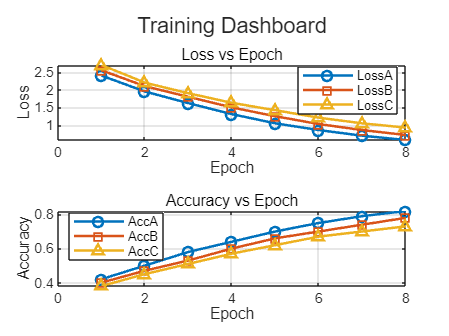

clear; clc

%% (a) 위 데이터를 table TrainLog로 생성
Epoch = (1:8)';

LossA = [2.40; 1.95; 1.62; 1.31; 1.05; 0.86; 0.70; 0.58];
LossB = [2.55; 2.10; 1.80; 1.50; 1.25; 1.03; 0.86; 0.72];
LossC = [2.70; 2.20; 1.90; 1.63; 1.42; 1.21; 1.05; 0.93];

AccA = [0.42; 0.50; 0.58; 0.64; 0.70; 0.75; 0.79; 0.82];
AccB = [0.40; 0.47; 0.53; 0.60; 0.66; 0.70; 0.74; 0.78];
AccC = [0.38; 0.45; 0.51; 0.57; 0.62; 0.67; 0.70; 0.73];

TrainLog = table(Epoch, LossA, LossB, LossC, AccA, AccB, AccC);

%% (b) tiledlayout(2,1)을 이용하여 2행 1열 레이아웃 생성
figure
t = tiledlayout(2, 1);

%% (c) 첫 번째 tile: Epoch에 따른 LossA, LossB, LossC

nexttile(t)
plot(TrainLog.Epoch, TrainLog.LossA, '-o', 'LineWidth', 1.5)
hold on
plot(TrainLog.Epoch, TrainLog.LossB, '-s', 'LineWidth', 1.5)
plot(TrainLog.Epoch, TrainLog.LossC, '-^', 'LineWidth', 1.5)
hold off

legend('LossA', 'LossB', 'LossC', 'Location', 'best')
xlabel('Epoch')
ylabel('Loss')
title('Loss vs Epoch')
grid on

%% (d) 두 번째 tile: Epoch에 따른 AccA, AccB, AccC
nexttile(t)
plot(TrainLog.Epoch, TrainLog.AccA, '-o', 'LineWidth', 1.5)
hold on
plot(TrainLog.Epoch, TrainLog.AccB, '-s', 'LineWidth', 1.5)
plot(TrainLog.Epoch, TrainLog.AccC, '-^', 'LineWidth', 1.5)
hold off

legend('AccA', 'AccB', 'AccC', 'Location', 'best')
xlabel('Epoch')
ylabel('Accuracy')
title('Accuracy vs Epoch')
grid on

%% (f) 전체 tiled layout 제목 설정
title(t, 'Training Dashboard')

# 11

clear; clc

%% (a) 행렬 A 생성
A = [ 3  -1   5  -2   4;
     -4   6  -3   2   1;
      7  -5   8  -1   0;
     -2   4  -6   9   3;
      5  -3   2  -4   6];

%% (b) 원본 행렬 A를 복사하여 A_clean 생성
A_clean = A;

%% (c), (d) 중첩 for문으로 모든 원소 검사 후 음수이면 0으로 변경
for i = 1:size(A_clean, 1)
    for j = 1:size(A_clean, 2)
        if A_clean(i, j) < 0
            A_clean(i, j) = 0;
        end
    end
end

%% (e) 정제 전후 비교 출력
disp('Original matrix A:')

Original matrix A:


disp(A)

     3    -1     5    -2     4
    -4     6    -3     2     1
     7    -5     8    -1     0
    -2     4    -6     9     3
     5    -3     2    -4     6




disp('Cleaned matrix A_clean:')

Cleaned matrix A_clean:


disp(A_clean)

     3     0     5     0     4
     0     6     0     2     1
     7     0     8     0     0
     0     4     0     9     3
     5     0     2     0     6



# 12

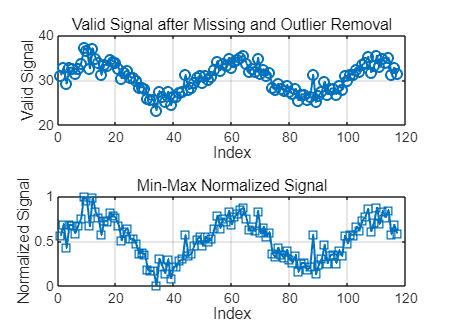

clear; clc

%% (a) 난수 seed 고정
rng(0)

%% (b) t = 1, 2, ..., 120인 열벡터 생성
t = (1:120)';

%% (c) signal 생성
signal = 30 + 4*sin(t/8) + randn(120, 1);

%% (d) 15번째, 45번째, 90번째 값을 NaN으로 변경
signal([15, 45, 90]) = NaN;

%% (e) 이상치 삽입
signal(30) = 80;
signal(75) = -20;
signal(110) = 95;

%% (f) 결측치 위치와 결측치 개수 저장
idxMissing = isnan(signal);

numMissing = sum(idxMissing);

%% (g) 결측치를 제외하고 계산한 평균으로 결측치 대체
muSignal = mean(signal, 'omitnan');

signalFilled = signal;
signalFilled(idxMissing) = muSignal;

%% (h) signalFilled의 평균과 표준편차를 이용하여 3sigma 기준 이상치 검출
muFilled = mean(signalFilled);
sigFilled = std(signalFilled);

idxOutlier = abs(signalFilled - muFilled) > 3 * sigFilled;

%% (i) signalFilled를 복사하여 signalClean 생성 후 이상치 위치를 NaN으로 변경
signalClean = signalFilled;
signalClean(idxOutlier) = NaN;

%% (j) signalClean에서 NaN이 아닌 값만 추출
validSignal = signalClean(~isnan(signalClean));

%% (k) validSignal을 Min-Max 정규화
minVal = min(validSignal);
maxVal = max(validSignal);

normSignal = (validSignal - minVal) ./ (maxVal - minVal);

%% (l) normSignal의 평균과 분산 계산
finalMean = mean(normSignal);
finalVar = var(normSignal);

%% (m) validSignal과 normSignal을 하나의 figure에서 위아래 두 개의 tile로 표시
figure

tiledlayout(2, 1)

nexttile
plot(validSignal, '-o', 'LineWidth', 1.2)
grid on
xlabel('Index')
ylabel('Valid Signal')
title('Valid Signal after Missing and Outlier Removal')

nexttile
plot(normSignal, '-s', 'LineWidth', 1.2)
grid on
xlabel('Index')
ylabel('Normalized Signal')
title('Min-Max Normalized Signal')

nexttile(2)
xlim([0 120])
ylim([0.00 1.00])

# 13

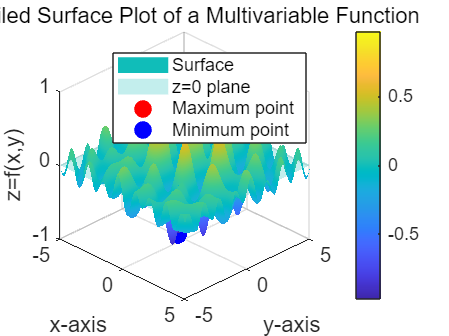

clear; clc

%% (a) x, y 범위 설정 및 meshgrid 생성
x = -5:0.05:5;
y = -5:0.05:5;

[X, Y] = meshgrid(x, y);

%% (b) 원소별 연산으로 Z 계산
Z = exp(-0.08 * (X.^2 + Y.^2)) .* sin(3*X) .* cos(2*Y) ...
    + 0.15 * sin(X .* Y);

%% (c) surf를 이용한 3차원 곡면 그래프
figure

hSurf = surf(X, Y, Z);
hold on

%% (d) shading interp, colorbar 추가
shading interp
colorbar

%% (i) z = 0 평면을 반투명 기준면으로 표시
Z0 = zeros(size(Z));

hPlane = surf(X, Y, Z0);
hPlane.FaceAlpha = 0.25;
hPlane.EdgeColor = 'none';

%% (j) 곡면의 최대값과 최소값 계산
[maxZ, idxMax] = max(Z(:));
[minZ, idxMin] = min(Z(:));

%% (k) 최대값과 최소값 위치의 (x, y, z) 좌표 찾기
[rowMax, colMax] = ind2sub(size(Z), idxMax);
[rowMin, colMin] = ind2sub(size(Z), idxMin);

maxPoint = [X(rowMax, colMax), Y(rowMax, colMax), maxZ];
minPoint = [X(rowMin, colMin), Y(rowMin, colMin), minZ];

%% (l) 최대점과 최소점을 그래프 위에 marker로 표시
hMax = plot3(maxPoint(1), maxPoint(2), maxPoint(3), ...
             'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

hMin = plot3(minPoint(1), minPoint(2), minPoint(3), ...
             'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');

%% (e) 축 label 설정
xlabel('x-axis')
ylabel('y-axis')
zlabel('z=f(x,y)')

%% (f) 그래프 제목 설정
title('Detailed Surface Plot of a Multivariable Function')

%% (g) grid on 및 축 글자 크기 설정
grid on

ax = gca;
ax.FontSize = 12;

%% (h) 관찰 각도 지정
view(45, 30)

%% (l) legend 추가
legend([hSurf, hPlane, hMax, hMin], ...
       {'Surface', 'z=0 plane', 'Maximum point', 'Minimum point'}, ...
       'Location', 'best')

%% (m) 최종 그래프를 PNG 파일로 저장
saveas(gcf, 'complex_surface.png')